clear all
% Run on the folder storing sleep stage files


%%Align time of sleep stage data and Calculate average sleep time schedule
folderName = 'Healthy';% Select 'PTSD' or 'Healthy'
[T,N]=load_patient_data_raw_withName(folderName);% Load all subject data.
% T: sleep stage data by numeric values
% one subject data in each cell
% one cell data > row: bin(30s), column: each night
% 0==Wake, 1==N1, 2==N2, 3==N3, 4==R, 5==NotScored
% N: subject IDs (column1) and their recording IDs (column2)
data = stage_replace(T, 0); % Separate Wake from others
% data: 0/1 sleep stage data (1==Wake 0==sleep stages)

A = get_record_start_time(folderName);% Check the time of the first epoch of the recording
[T_match, A] = align_time(A,N,data);% Align time across recordings within each subject
% T_match: time-aligned sleep stage data from the earliest sleep stage appearance to the latest sleep stage appearance
% A: sleep time schedule
% one subject data in each cell
% one cell data 
% > row: each night, 
%   column: [subject ID, recording ID, recording start time, recording start time*, 
%            time difference [m] from the earliest recording start time, sleep onset time*, sleep offset time*, recording end time*]
%           *minutes from 0:00


% Calculate average sleep time schedule for each subject
AverageTime = get_average_schedule(A);
% row: each subject
% column: [recording start time*, sleep onset time*, sleep offset time*, recording end time*, midpoint of the sleep*, recording duration [m], sleep duration [m]]
%          *minutes from 0:00

%%Calculate Sleep Regularity Index (SRI)
SRI = get_SRI(T_match);
% one subject data in each cell


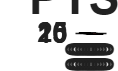

%%Make a figure of average sleep schedule
figure; hold on;
for i = 1:size(AverageTime,1)
    % box from recording start to end
    rectangle('Position', [AverageTime(i,1), i-0.35, AverageTime(i,6), 0.7], ...
              'EdgeColor', 'black', 'LineWidth', 1.5);

     
    % lines at sleep onset and end
    line([AverageTime(i,2), AverageTime(i,2)], [i-0.35, i+0.35], 'Color', 'black', 'LineWidth', 1.5);
    line([AverageTime(i,3), AverageTime(i,3)], [i-0.35, i+0.35], 'Color', 'black', 'LineWidth', 1.5);
    

    % recording start to sleep onset
    fill([AverageTime(i,1), AverageTime(i,2), AverageTime(i,2), AverageTime(i,1)], ...
         [i-0.35, i-0.35, i+0.35, i+0.35], [1 1 1], 'EdgeColor', 'none'); 

    % sleep onset to offset
    if strcmp(folderName, 'Healthy')
        fill([AverageTime(i,2), AverageTime(i,3), AverageTime(i,3), AverageTime(i,2)], ...
         [i-0.35, i-0.35, i+0.35, i+0.35], [0.0745 0.6235 1.0000], 'EdgeColor', 'none');
    else
        fill([AverageTime(i,2), AverageTime(i,3), AverageTime(i,3), AverageTime(i,2)], ...
         [i-0.35, i-0.35, i+0.35, i+0.35], [1.0000 0.3882 0.3882], 'EdgeColor', 'none');
    end

    % sleep offset to recoridng end
    fill([AverageTime(i,3), AverageTime(i,4), AverageTime(i,4), AverageTime(i,3)], ...
         [i-0.35, i-0.35, i+0.35, i+0.35], [0 0 0], 'EdgeColor', 'none'); 

    % lines at midpoint of the sleep
    line([AverageTime(i,5), AverageTime(i,5)], [i-0.35, i+0.35], 'Color', 'black', 'LineWidth', 1.5);

end

% x and y axis setting
xlabel('Time', 'FontSize',20,'FontWeight','bold');
ylabel('Participant ID', 'FontSize',20,'FontWeight','bold');

xlim([-400, 800]);
xticks([-360 -240 -120 0 120 240 360 480 600 720]);
xticklabels({'18:00', '20:00', '22:00', '0:00', '2:00', '4:00', '6:00', '8:00', '10:00', '12:00'});
yticks(0:5:30);

ax = gca;
ax.FontSize = 20;
ax.FontWeight = 'bold'; 

% Title
title(folderName, 'FontSize', 35, 'FontWeight', 'bold'); 


function A = get_record_start_time(folderName)
% Purpose: Check the time of the first epoch of the recording
% folderName = 'Healthy' or 'PTSD'
% one patient data in each cell
% one cell data 
% > row: each night, 
%   column: [subject ID, recording ID, recording start time, recording start time as minutes from 0:00, time difference [m] from the earliest recording start time]


% Get the current working directory
currentDir = pwd;

% Combine the current directory with the folder name
folderPath = fullfile(currentDir, folderName);
folders=get_folders_list(folderPath); % Get all subjects ID

% Initiate an empty array to store recording start times
A = [];

% Loop through each subject data
for i=1:size(folders,2)
    % Initiate an empty array to store recording start times for each subject
    N=[];
    % Get a path of each subject folder
    NightPath=fullfile(folderPath, folders(i));
    files = dir(fullfile(NightPath{:},filesep, '*.csv'));

    % Loop through each night data
    for fileIndex = 1:length(files)
        % Get the file name
        fileName = files(fileIndex).name; 
        % Construct the full file path
        filePath = fullfile(NightPath{:}, fileName);

        fileName = extractBefore(fileName, '.csv');
        parts = split(fileName, '_'); % Extract recording ID 
        

        % Load the CSV file into a table
        data = readtable(filePath,'VariableNamingRule', 'preserve');
        rawTime = data{2,2}; % Extract recording start time
        
        % If time has no date information, add fake date
        try
        fakeDate = datetime('1900-01-01');
        rawTime = fakeDate + rawTime;
        end

        % Adjust timestamps to 30 second interval
        if rawTime.Second < 30
            rawTime.Second = 0;
        else
            rawTime.Second = 30;
        end
        
        % Express timestamp as minutes relative to 0:00
        minute = rawTime.Hour*60 + rawTime.Minute + rawTime.Second/60;
        if rawTime.Hour > 12
            minute = minute - 1440;
        end

        
        N{end+1,1} = folders{i};% subject ID
        N{end,2} = parts{2}; % recording ID
        N{end,3} = string(datestr(rawTime, 'HH:MM:SS')); % recording start time
        N{end,4} = minute; % recording start time as minutes
        
    end

    % Find the earliest recording start time among nights within one subject
    minRS = min(cell2mat(N(:,4)));
    % Calculate the time difference [m] from the earliest time
    N(:,5) = num2cell(cell2mat(N(:,4)) - minRS);
    A{i,1} =N;
end
end

function folders=get_folders_list(folderPath)

contents = dir(folderPath);
% Initialize an empty cell array to store folder names
folders = {};

% Loop through each item in the directory
for i = 1:length(contents)
    % Check if the item is a directory and not '.' or '..'
    if contents(i).isdir && ~strcmp(contents(i).name, '.') && ~strcmp(contents(i).name, '..')
        % Append the folder name to the cell array
        folders{end+1} = contents(i).name;
    end
end
end

function [T_match, A]=align_time(A,S,data)
% Purpose: Align time among recordings within each subject
% A: recording start times -> sleep time schedule
% one subject data in each cell
% one cell data 
% > row: each night, 
%   column: [subject ID, recording ID, recording start time, recording start time*, time difference [m] from the earliest recording start time,
%            sleep onset time*, sleep offset time*, recording end time*]
%           *minutes from 0:00

% S: subject and recording ID, data: 0/1 sleep stage data 
% -> T_match: time-aligned sleep stage data from the earliest sleep stage appearance to the latest sleep stage appearance


% Initiate an empty array to store time-aligned data
T_match =[];

% Loop through each subject data
for i = 1:size(A,1)
    N = A{i,1};% Extract one subject data of record start times
    % Initiate an empty array to store time-aligned data for each subject
    match = [];

    % Loop through each night data
    for k = 1:size(N,1)
        ID = N{k,1}; % subject ID
        Night = N{k,2}; % recording ID
        searchID = find(strcmp(S(:,1),ID)); % Find subject ID from sleep data
        searchNight = find(strcmp(S{searchID,2},Night)); % Find recording ID from sleep data
        if isempty(searchID) || isempty(searchNight)
            warning("ID or Night not found: %s, %s", ID, Night);
            continue;
        end
        SleepStage = data{searchID,1}(:,searchNight); % Extract sleep data linked to the IDs
        SleepStage(isnan(SleepStage))=[];

        all = size(SleepStage,1);% Calculate recording duration
        start = find(SleepStage == 0,1,'first'); % Calculate time from recording start to sleep onset
        finish = find(SleepStage == 0,1,'last'); % Calculate time from recording start to sleep offset
        N{k,6} = N{k,4} + (start-1)/2; % sleep onset
        N{k,7} = N{k,4} + finish/2; % sleep offset
        N{k,8} = N{k,4} + all/2; % recording end
        if N{k,5} > 0 % If there is a time difference from the earliest recording
            % Add Wake (==1) to the beggining for time alignment
            onesToAdd = ones(N{k,5}*2, 1); 
            SleepStage = [onesToAdd; SleepStage];
        end
        % Add Wake (==1) to the end of early ending recordings to match the total duration
        match = catpad(2,match,SleepStage,'padval',1); 
    end
    A{i,1} = N; % Update sleep time schedule information

    % Delete data until the first occurrence of sleep stage (==0) across all recordings
    rowHasZero = any(match == 0,2);
    firstRow = find(rowHasZero,1,'first');
    match(1:firstRow-1,:) = [];
    % Delete data after the last occurrence of sleep stage (==0) across all recordings
    rowHasZero = any(match == 0,2);
    lastRow = find(rowHasZero,1,'last');
    match(lastRow+1:end,:) = [];

    
    T_match{i,1} = match;
    
end
end

function AverageTime = get_average_schedule(A)
% Puporse: Average sleep schedule across recordings within each subject
% A: sleep time schedule
% AverageTime:
% row: each subject
% column: [recording start time*, sleep onset time*, sleep offset time*, recording end time*, midpoint of the sleep*, recording duration [m], sleep duration [m]]
%          *minutes from 0:00


% Initiate an empty array to store averaged sleep schedule
AverageTime = [];
for i = 1:size(A,1)
    N = A{i,1}; % Extract sleep schedule information of one subject
    AverageTime{i,1} = mean(cell2mat(N(:,4)));% recording start
    AverageTime{i,2} = mean(cell2mat(N(:,6)));% sleep onset
    AverageTime{i,3} = mean(cell2mat(N(:,7)));% sleep offset
    AverageTime{i,4} = mean(cell2mat(N(:,8)));% recording end
    AverageTime{i,5} = (AverageTime{i,2}+AverageTime{i,3})/2;% midpoint of the sleep
    AverageTime{i,6} = AverageTime{i,4} - AverageTime{i,1};% recording duration
    AverageTime{i,7} = AverageTime{i,3} - AverageTime{i,2};% sleep duration
end

AverageTime=sortrows(cell2mat(AverageTime),5,'descend'); % Sort subjects by midpoint of the sleep

end

function SRI = get_SRI(T_match)
% Purpose: Calulate Sleep Regularity Index (SRI)
% T_match: time-aligned sleep stage data
% Sleep Regularity Index (SRI):
% the probability that a person is in the same state (asleep or awake) at the same clock time on two consecutive nights.
% SRI = (200 * C / N) - 100
% C: total count of matched sleep/wake states at the same clock time across consecutive nights
% N: total number of comparisons made across all time points and all night pairs
%    (i.e., number of time points × number of night pairs)

% Initiate an empty array to store SRI
SRI = [];
% Loop through each subject data
for i = 1:size(T_match,1)
    M = T_match{i,1}; % Extract one subject data
    sri=NaN;
    if size(M,2)>1 % more than two night recordings
        C=0; % number of time points where the sleep/wake state is the same across consecutive days
        for k = 1:size(M,1) % Loop through all epochs (row)
            for n = 1:size(M,2)-1 % Loop through all night pairs (columns)
                if M(k,n) == M(k,n+1)
                    C = C+1; % Count the number of time points where the sleep/wake state is the same
                end
            end
        end
        sri = (200*C)/(size(M,1)*(size(M,2)-1))-100; % average agreement across consecutive night pairs (scale: -100~100)
    end
    SRI{i,1} = sri;
end
end
